syms theta(t) phi(t) psi(t) t;  %generalized coord
syms m1 m2 m3 l0 l1 l2 l3 I1 I2 I3 r1 r2 r3 g;   %link parameters
syms a; %placeholder variable
syms c1 c2; %lagrange multipliers(2 constraint eqns)
syms tau1 tau2 tau3;    %Joint torques
syms dtht dphi dpsi;

%System parameters
m1 = subs(m1,m1,1);
m2 = subs(m2,m2,1);
m3 = subs(m3,m3,1);

l0 = subs(l0,l0,0.2);
l1 = subs(l1,l1,0.06);
l2 = subs(l2,l2,0.14);
l3 = subs(l3,l3,0.16);

I1 = subs(I1,I1,(1/12)*m1*l1*l1);
I2 = subs(I2,I2,(1/12)*m2*l2*l2);
I3 = subs(I3,I3,(1/12)*m3*l3*l3);

r1 = subs(r1,r1,l1/2);
r2 = subs(r2,r2,l2/2);
r3 = subs(r3,r3,l3/2);

g = subs(g,g,9.8);

%% Done

%For forward dynamics, the joints torques are given, it is 0

tau1 = subs(tau1,tau1,0);
tau2 = subs(tau2,tau2,0);
tau3 = subs(tau3,tau3,0);

%% Done

theta_dot = diff(theta(t),t);
phi_dot = diff(phi(t),t);
psi_dot = diff(psi(t),t);
theta_dot_dot = diff(theta_dot,t);
phi_dot_dot = diff(phi_dot,t);
psi_dot_dot = diff(psi_dot,t);
q = [theta(t);phi(t);psi(t)];
q_dot = [theta_dot;phi_dot;psi_dot];
q_dot_dot = [theta_dot_dot;phi_dot_dot;psi_dot_dot];
Rz = [cos(a) -sin(a) 0;sin(a) cos(a) 0;0 0 1];
g0 = [0;-g;0];

%link-1
R1_0 = subs(Rz,a,theta(t));
w1_1 = [0;0;theta_dot];
v1_1 = [0;0;0];
pC1_1 = [r1;0;0];
vC1_1 = v1_1 + (cross(w1_1,pC1_1));
w1_0 = R1_0*w1_1;
v1_0 = R1_0*v1_1;
pC1_0 = R1_0*pC1_1;
vC1_0 = R1_0*vC1_1;
vC1_0 = subs(vC1_0,theta_dot,dtht); 
KE1=simplify(0.5*m1*(simplify(vC1_0(1)^2 + vC1_0(2)^2)) + (0.5*I1*dtht^2)); 
%KE1 = (0.5*m1*(dot(vC1_0,vC1_0))) + (0.5*dot(w1_0,I1*w1_0));
KE1diff=subs(KE1,dtht,theta_dot);
PE1 = simplify(-(m1*((g0(2)*pC1_0(2)))));

%link-2
R2_0 = subs(Rz,a,phi(t)+theta(t)-360);
w2_2 = [0;0;theta_dot+phi_dot];
v2_2 = [l1*theta_dot*sin(phi);l1*theta_dot*cos(phi);0];
pC2_2 = [r2;0;0];
vC2_2 = v2_2 + (cross(w2_2,pC2_2));
w2_0 = formula(R2_0*w2_2);
v2_0 = formula(R2_0*v2_2);
pC2_0 = formula(R2_0*pC2_2 + (R1_0*[l1;0;0])); 
vC2_0 = formula(R2_0*vC2_2);
vC2_0 = simplify(subs(vC2_0,[theta_dot,phi_dot],[dtht,dphi]));
KE2=simplify(0.5*m2*(simplify(vC2_0(1)^2 + vC2_0(2)^2)) + (0.5*I2*(dtht+dphi)^2));
KE2diff=subs(KE2,[dtht,dphi],[theta_dot,phi_dot]);
%KE2 = (0.5*m2*(dot(vC2_0,vC2_0))) + (0.5*dot(w2_0,I2*w2_0));%do not use the dot operator
PE2 = simplify(-(m2*((g0(2)*pC2_0(2)))));

%link-3
R3_0 = subs(Rz,a,psi(t));
w3_3 = [0;0;psi_dot];
v3_3 = [0;0;0];
pC3_3 = [r3;0;0];
vC3_3 = v3_3 + (cross(w3_3,pC3_3));
w3_0 = R3_0*w3_3;
v3_0 = R3_0*v3_3;
pC3_0 = R3_0*pC3_3;
vC3_0 = R3_0*vC3_3;
vC3_0 = simplify(subs(vC3_0,psi_dot,dpsi));
KE3 = simplify(0.5*m3*(simplify(vC3_0(1)^2 + vC3_0(2)^2)) + (0.5*I3*dpsi^2));
KE3diff = subs(KE3,dpsi,psi_dot);
%KE3 = (0.5*m3*(dot(vC3_0,vC3_0))) + (0.5*dot(w3_0,I1*w3_0));
PE3 = simplify(-(m3*((g0(2)*pC3_0(2)))));

%constraint equations
cons1 = (l1*cos(theta(t))) + (l2*cos(theta(t)+phi(t))) - (l3*cos(psi(t))) - l0;
cons2 = (l1*sin(theta(t))) + (l2*sin(theta(t)+phi(t))) - (l3*sin(psi));

L = simplify((KE1 + KE2 + KE3)-(PE1+PE2+PE3));
L = subs(L,[dtht,dphi,dpsi],[theta_dot,phi_dot,psi_dot]);

%Laplace equations
eqn_theta = simplify(diff(diff(L,theta_dot),t) - diff(L,theta(t)) - tau1 - (c1*(diff(cons1,theta(t))+c2*(diff(cons2,theta(t))))));
eqn_phi = simplify(diff(diff(L,phi_dot),t) - diff(L,phi(t)) - tau2 - (c1*(diff(cons1,phi(t))+c2*(diff(cons2,phi(t))))));
eqn_psi = simplify(diff(diff(L,psi_dot),t) - diff(L,psi(t)) - tau3 - (c1*(diff(cons1,psi(t))+c2*(diff(cons2,psi(t))))));


%Constructing matrices
syms a b c;
eqn_theta = subs(eqn_theta,[diff(theta_dot,t),diff(phi_dot,t),diff(psi_dot,t)],[a,b,c]);
eqn_phi = subs(eqn_phi,[diff(theta_dot,t),diff(phi_dot,t),diff(psi_dot,t)],[a,b,c]);
eqn_psi = subs(eqn_psi,[diff(theta_dot,t),diff(phi_dot,t),diff(psi_dot,t)],[a,b,c]);
eqn_theta = simplify(subs(eqn_theta,[diff(theta,t),diff(phi,t),diff(psi,t)],[dtht,dphi,dpsi]));
eqn_phi = simplify(subs(eqn_phi,[diff(theta,t),diff(phi,t),diff(psi,t)],[dtht,dphi,dpsi]));
eqn_psi = simplify(subs(eqn_psi,[diff(theta,t),diff(phi,t),diff(psi,t)],[dtht,dphi,dpsi]));

M1 = simplify(formula([(diff(eqn_theta,a)) (diff(eqn_theta,b)) (diff(eqn_theta,c))]));
M2 = simplify(formula([(diff(eqn_phi,a)) (diff(eqn_phi,b)) (diff(eqn_phi,c))]));
M3 = simplify(formula([(diff(eqn_psi,a)) (diff(eqn_psi,b)) (diff(eqn_psi,c))]));
M = [M1;M2;M3];

for i = 1:3
    for j = 1:3

    end
end

C_matrix = zeros(3,3);
C_matrix = symmatrix(C_matrix);
C_matrix = symmatrix2sym(C_matrix);

for i=1:3
    for j=1:3
        for k=1:3
            temp = simplify(formula(0.5*((diff(M(i,j),q(k,1))) + ( ...
                diff(M(i,k),q(j,1))) - (diff(M(k,j),q(i,1))))*q_dot(k,1)));
            C_matrix(i,j) = C_matrix(i,j) + temp;
        end
    end
end

G_matrix = zeros(3,1);
G_matrix = symmatrix(G_matrix);
G_matrix = symmatrix2sym(G_matrix);
PE = PE1 + PE2 + PE3;

for i=1:3
    G_matrix(i,1) = diff(PE,q(i,1));
end


psi_Matrix = formula([diff(cons1,q(1,1)) diff(cons1,q(2,1)) diff(cons1,q(3,1));diff(cons2,q(1,1)) diff(cons2,q(2,1)) diff(cons2,q(3,1))]);
psi_Matrix_dot = formula(diff(psi_Matrix,t));

%Lagrange_matrix = symmatrix('Lagrange_matrix',[2,1]);
tau = [tau1;tau2;tau3];

Lagrange_matrix = -((psi_Matrix*(M\transpose(psi_Matrix))))\((psi_Matrix_dot*q_dot)+(psi_Matrix*(M\(tau-(C_matrix*q_dot)-G_matrix))));


%Using all the information to derive equations using ODE-45

tstart = 0;
tend = 5;
dt = 0.01;
n = 20;

[thinit,phinit,psinit] = FourB_IK(0);
xinit = [thinit phinit psinit 0 0 0];

X_final = zeros(1,6);
tspan2 = zeros(1,1);

for ti = tstart:dt:tend-dt
    M_ode = double(subs(M,transpose(q),(xinit(1:3))));

    C_ode1 = subs(C_matrix,transpose(q_dot),(xinit(4:6)));
    C_ode = double(subs(C_ode1,transpose(q),(xinit(1:3))));

    G_ode = double(subs(G_matrix,transpose(q),(xinit(1:3))));
    
    constr_ode = double(subs(psi_Matrix,transpose(q),(xinit(1:3))));

    constr_d_ode_1 = subs(psi_Matrix_dot,transpose(q_dot),(xinit(4:6)));
    constr_dot_ode = double(subs(constr_d_ode_1,transpose(q),(xinit(1:3))));

    tspan = [ti ti+dt];
    [time,x_ode] = ode45(@(time,x_ode)FourBdynamicsIntegratingFunc(time,x_ode,(M_ode),(C_ode),(G_ode),(constr_ode),(constr_dot_ode)), tspan, xinit);
    xinit = x_ode(size(x_ode,1),:);
    X_final = [X_final;x_ode(size(x_ode,1),:)];
    tspan2 = [tspan2;ti+dt];
end


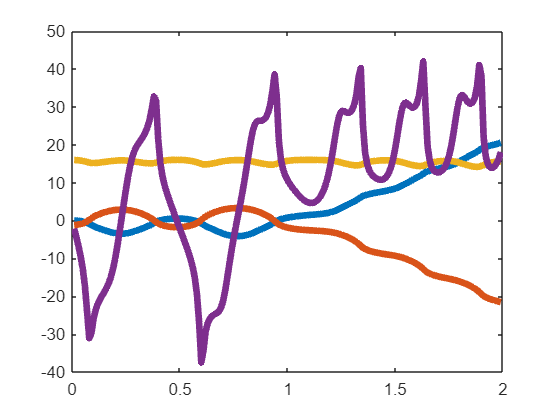

tlen = 200;
phi3 = 4*pi-(X_final(2:tlen,1)+X_final(2:tlen,2)+X_final(2:tlen,3));
plot(tspan2(2:tlen,1),X_final(2:tlen,1),tspan2(2:tlen,1),X_final(2:tlen,2),tspan2(2:tlen,1),phi3,tspan2(2:tlen,1),X_final(2:tlen,4),'Linewidth',4);

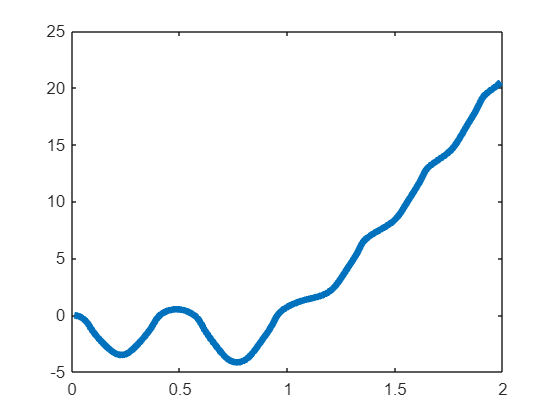

plot(tspan2(2:tlen,1),X_final(2:tlen,1),'Linewidth',4)

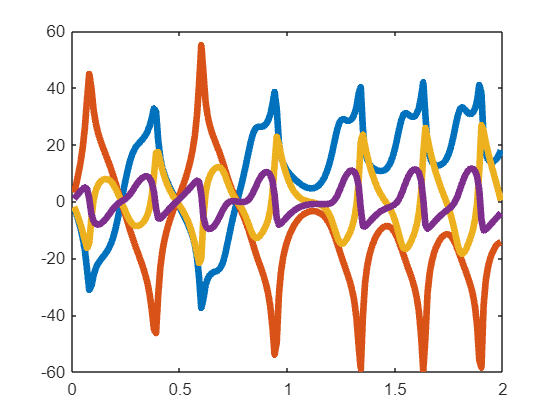

phi3_t = -(X_final(2:tlen,4)+X_final(2:tlen,5)+X_final(2:tlen,6));
plot(tspan2(2:tlen,1),X_final(2:tlen,4),tspan2(2:tlen,1),X_final(2:tlen,5),tspan2(2:tlen,1),phi3_t,tspan2(2:tlen,1),X_final(2:tlen,6),'Linewidth',4);

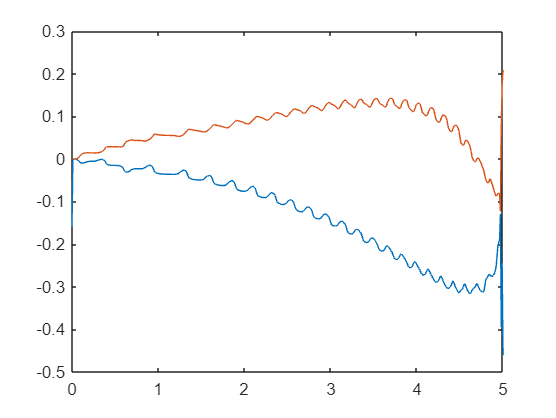

%Verification of solution
constt_1 = (l1*cos(X_final(:,1))) + (l2*cos(X_final(:,1)+X_final(:,2))) - (l3*cos(X_final(:,3))) - l0;
constt_2 = (l1*sin(X_final(:,1))) + (l2*sin(X_final(:,1)+X_final(:,2))) - (l3*sin(X_final(:,3)));
n_const = double(diag(constt_1*transpose(constt_2)));
plot(tspan2,constt_1,tspan2,constt_2);

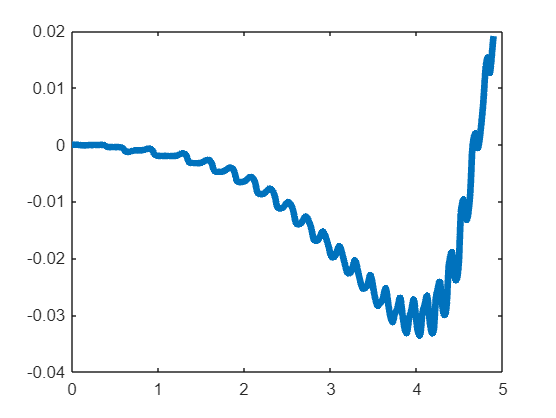

plot(tspan2(1:490,1),n_const(1:490,1),'Linewidth',4);

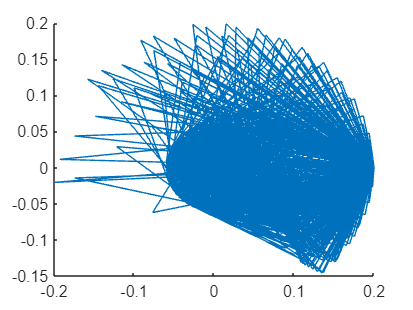

%Animating solution 
X_pos = zeros(1,4);
Y_pos = zeros(1,4);
figure();
hold on

for i = 1:size(tspan2)
X_pos(1,1) = 0;
X_pos(1,2) = l1*cos(X_final(i,1));
X_pos(1,3) = (l1*cos(X_final(i,1))) + (l2*cos(X_final(i,1)+X_final(i,2)));
X_pos(1,4) = l0;

Y_pos(1,1) = 0;
Y_pos(1,2) = l1*sin(X_final(i,1));
Y_pos(1,3) = (l1*sin(X_final(i,1))) + (l2*sin(X_final(i,1)+X_final(i,2)));
Y_pos(1,4) = 0;

line([X_pos(1,1) X_pos(1,2)],[Y_pos(1,1) Y_pos(1,2)]);
line([X_pos(1,2) X_pos(1,3)],[Y_pos(1,2) Y_pos(1,3)]);
line([X_pos(1,3) X_pos(1,4)],[Y_pos(1,3) Y_pos(1,4)]);
line([X_pos(1,4) X_pos(1,1)],[Y_pos(1,4) Y_pos(1,1)]);
end
hold off

function dxdt = FourBdynamicsIntegratingFunc(time,x,mass,coriolis,gravity,constraint,constraint_dot)
    
    M_ode = mass;
    C_ode = coriolis;
    G_ode = gravity;
    constr_ode = constraint;
    constr_dot_ode = constraint_dot;

    f = (-C_ode*x(4:6)) - G_ode;
    T1 = constr_ode*(M_ode\transpose(constr_ode));
    T2 = (constr_ode*(M_ode\f))+(constr_dot_ode*x(4:6));
    dxdt(1:3) = x(4:6);
    dxdt(4:6) = M_ode\(f-(transpose(constr_ode)*(T1\T2)));
    dxdt = transpose(dxdt);

end


function [th,ph,ps] = FourB_IK(thf)
    l0 = 0.2;
    l1 = 0.06;
    l2 = 0.14;
    l3 = 0.16;

    syms t1 t2 t3;
    cons1 = (l1*cos(t1)) + (l2*cos(t1+t2)) - (l3*cos(t3)) - l0;
    cons2 = (l1*sin(t1)) + (l2*sin(t1+t2)) - (l3*sin(t3));
    
    sol = solve([cons1,cons2],[t2,t3]);
    th = thf;
    ph = double(subs(sol.t2(1),t1,thf));
    ps = double(subs(sol.t3(1),t1,thf));

end